# Writing an ODE Function, part 1

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Do not edit. This code solves the ODE system and visualizes the solution.

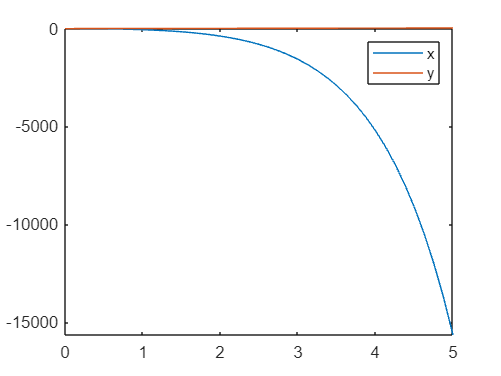

tRange = [0 5];
Y0 = [1;3];
[tSol,YSol] = ode45(@myODEfun,tRange,Y0);
% visualize solution
plot(tSol,YSol(:,1))
hold on
plot(tSol,YSol(:,2))
hold off
legend("x","y")

## Task 1

The local function `myODEfun` is located at the bottom of the script.

 Complete the expressions for `dxdt` and `dydt` so that `myODEfun` represents the following system of ODEs:

dx/dt=x−y2

dy/dt=6

function dYdt = myODEfun(t,Y)
x = Y(1);
y = Y(2);

% TODO - Complete expression for dxdt
dxdt=x-y.^2;

% TODO - Complete expression for dydt
dydt=6;

dYdt = [dxdt;dydt];
end